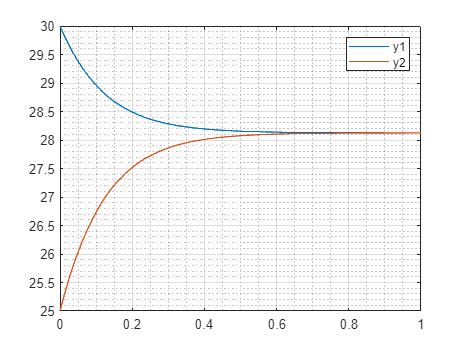

clear;clc;close all; % clean up
%22
x=linspace(0,1,100); % defining the time-grid
y0=[30,25]; % defining the temps at the left side
[x,sol]=ode23(@ODE_system,x,y0); % applying the solver
plot(x,sol(:,1),x,sol(:,2)); % visualizing the solutions
legend('y1','y2');grid on; grid minor;

function dydx = ODE_system(x,y) %defining the ODE system
dydx=zeros(2,1);
dydx(1)= -3*(y(1)-y(2)); % ode for y1
dydx(2)= 5*(y(1)-y(2)); % ode for y2
end